## 实验四 **边缘检测与图像分割**

### 边缘检测

#### 正交梯度算子法

使用正交模板、Roberts、Prewitt、Sobel算子进行边缘检测

1. 读入原图

clear;
origin_img = imread("eight.tif");
img_width = size(origin_img, 2);
img_height = size(origin_img, 1);
% 标准化
origin_std = im2double(origin_img);

2. 使用edge完成Roberts、Prewitt、Sobel算子边缘检测

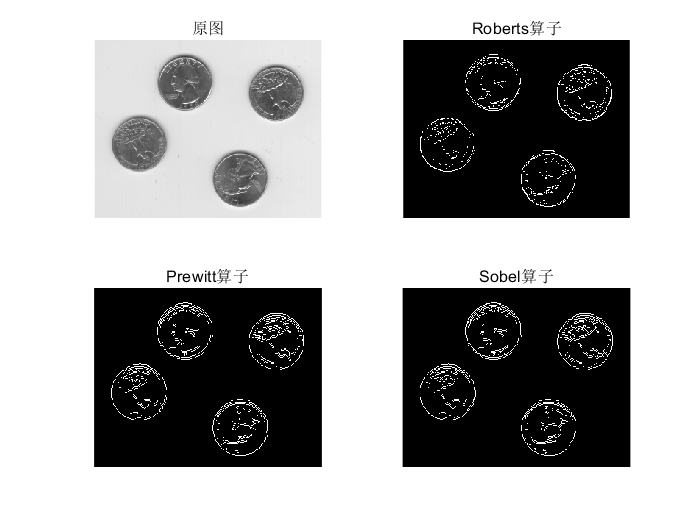

figure('Name','Edge函数进行边缘检测','NumberTitle','off');
subplot(2, 2, 1);
imshow(origin_std), title('原图')

E1 = edge(origin_std, 'Roberts');
subplot(2, 2, 2);
imshow(E1), title('Roberts算子')

E2 = edge(origin_std, 'Prewitt');
subplot(2, 2, 3);
imshow(E2), title('Prewitt算子')

E3 = edge(origin_std, 'Sobel');
subplot(2, 2, 4);
imshow(E3), title('Sobel算子')

3. 自己完成正交模板的边缘检测

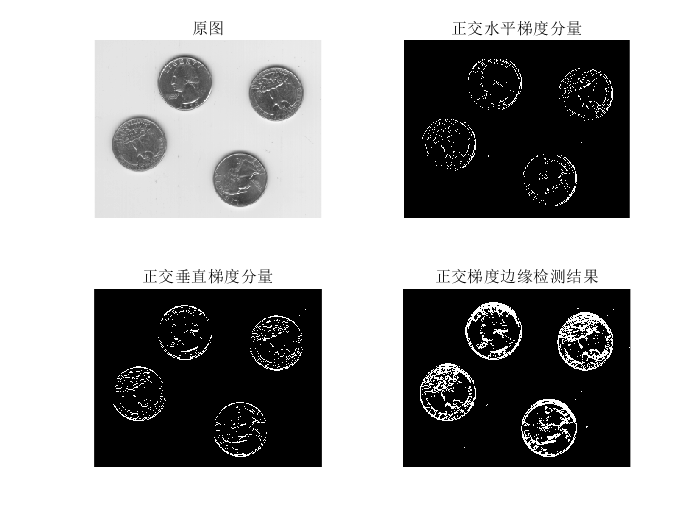

threshold = 0.09;
figure('Name','自己实现的正交梯度边缘检测','NumberTitle','off');
% 正交梯度的算子
orth = [0 0 0; -1 1 0; 0 0 0];
% 计算两个梯度分量
orth_hori = imfilter(origin_std, orth);
orth_vert = imfilter(origin_std, orth');
% 得到边缘信息
orth_edge = (orth_vert.^2+orth_hori.^2).^0.5;
% 转换为二值图像
orth_hori = imbinarize(orth_hori, threshold);
orth_vert = imbinarize(orth_vert, threshold);
orth_edge = imbinarize(orth_edge, threshold);
% 显示结果
subplot(2, 2, 1)
imshow(origin_std), title('原图')
subplot(2, 2, 2)
imshow(orth_hori), title('正交水平梯度分量')
subplot(2, 2, 3)
imshow(orth_vert), title('正交垂直梯度分量')
subplot(2, 2, 4)
imshow(orth_edge), title('正交梯度边缘检测结果')

4. 自己完成Sobel算子的边缘检测

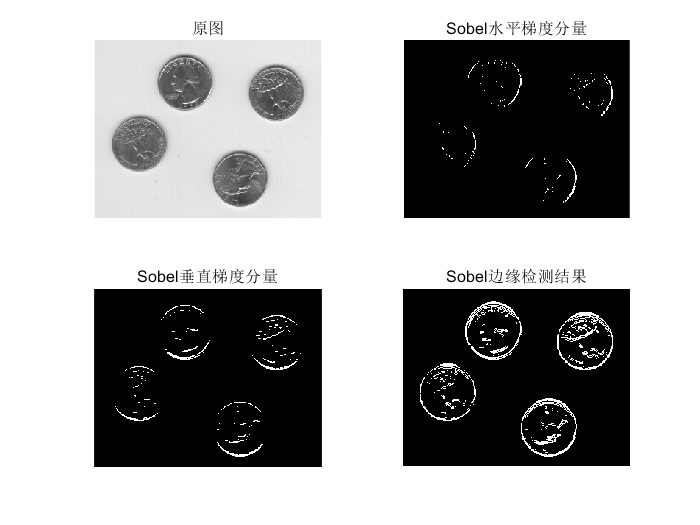

threshold = 0.18;
figure('Name','自己实现的Sobel边缘检测','NumberTitle','off');
sobel = [-1 0 1;-2 0 2;-1 0 1]/4;
% 水平方向和垂直方向的梯度分量
sobel_hori = imfilter(origin_std, sobel);
sobel_vert = imfilter(origin_std, sobel');
%  得到边缘信息
sobel_edge = (sobel_hori.^2+sobel_vert.^2).^0.5;
% 此处进行二值化图像转换
sobel_hori = imbinarize(sobel_hori, threshold);
sobel_vert = imbinarize(sobel_vert, threshold);
sobel_edge = imbinarize(sobel_edge, threshold);
% 显示结果
subplot(2, 2, 1)
imshow(origin_std), title('原图')
subplot(2, 2, 2)
imshow(sobel_hori), title('Sobel水平梯度分量')
subplot(2, 2, 3)
imshow(sobel_vert), title('Sobel垂直梯度分量')
subplot(2, 2, 4)
imshow(sobel_edge), title('Sobel边缘检测结果')

#### 方向梯度法

选用Kirsch方向梯度算子

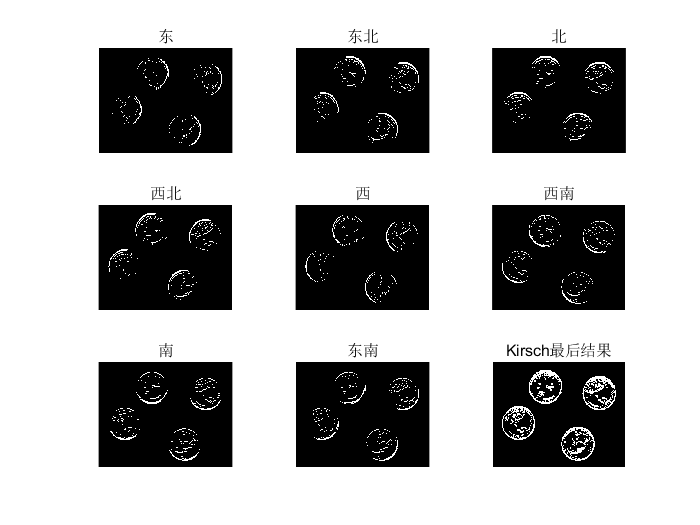

figure('Name','Kirsch方向梯度边缘检测','NumberTitle','off');
threshold = 0.09;
kirsch(:,:,1) = [-3 -3 5;-3 0 5;-3 -3 5];
kirsch(:,:,2) = [-3 5 5;-3 0 5; -3 -3 -3];
kirsch(:,:,3) = [5 5 5;-3 0 -3;-3 -3 -3];
kirsch(:,:,4) = [5 5 -3;5 0 -3;-3 -3 -3];
kirsch(:,:,5) = [5 -3 -3;5 0 -3;5 -3 -3];
kirsch(:,:,6) = [-3 -3 -3;5 0 -3; 5 5 -3];
kirsch(:,:,7) = [-3 -3 -3;-3 0 -3;5 5 5];
kirsch(:,:,8) = [-3 -3 -3;-3 0 5;-3 5 5];
kirsch = kirsch./15;
direction = ['东 ';'东北';'北 ';'西北';'西 ';'西南';'南 ';'东南'];

kirsch_res = zeros([size(origin_std),8]);

% 计算各方向上的梯度分量
for i=1:8
    kirsch_res(:,:,i) = imfilter(origin_std, kirsch(:,:,i));
end

% 取最大值得到最终的边缘
kirsch_edge = max(kirsch_res, [], 3);
% 进行二值化处理
kirsch_edge = imbinarize(kirsch_edge, threshold);

% 显示各方向上的梯度分量
for i=1:8
    kirsch_res(:,:,i) = imbinarize(kirsch_res(:,:,i), threshold);
    subplot(3, 3, i);
    imshow(kirsch_res(:,:,i)), title(strip(direction(i,:)));
end

subplot(3, 3, 9);
imshow(kirsch_edge), title('Kirsch最后结果');

### 图像分割

用直方图进行最优阈值的计算

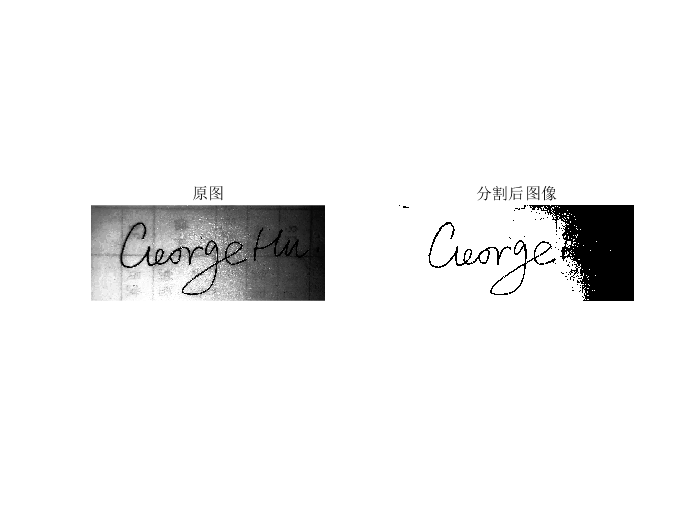

figure('Name','直方图最优阈值图像分隔','NumberTitle','off');
origin_img = imread("手写英文名.jpg");
origin_img = rgb2gray(origin_img);
origin_img = histeq(origin_img);

% 先获取直方图计数
h = imhist(origin_img);
h_count = h;
% 计算累计直方图
for i=2:256
    h_count(i) = h_count(i) + h_count(i-1);
end
last_diff = -1;
idx = -1;
% 测试阈值
for T=1:256
    P1 = h_count(T)/(img_height*img_width);
    P2 = (h_count(256)-h_count(T))/(img_height*img_width);
    if (last_diff < 0 && P1-P2 > 0)
        idx = T;
        break
    end
end

% 分别计算两类像素的均值
left = [1:T-1]*h(1:T-1)/h_count(T-1);
right = [T:256]*h(T:256)/h_count(256);
% 取均值的平均值为最后的最佳阈值
threshold = mean([left right]);

fore = origin_img;
% 二值化处理
fore(fore > threshold) = 255;
fore(fore <= threshold) = 0;

% 显示结果
subplot(1, 2, 1);
imshow(origin_img), title('原图');
subplot(1, 2, 2);
imshow(fore), title('分割后图像');

### 实验分析部分的尝试

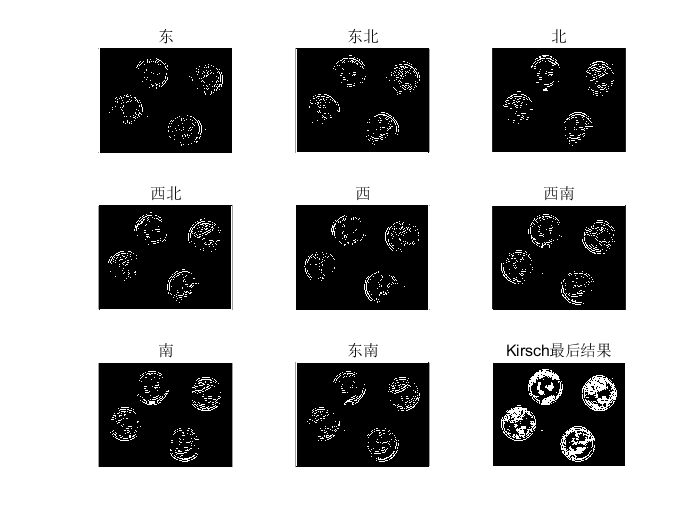

figure('Name','Kirsch前使用拉普拉斯算子进行锐化','NumberTitle','off');
% 3x3均值滤波
avg3x3 = fspecial('average', 3);
img_1 = imfilter(origin_std, avg3x3);

% 要用的拉普拉斯算子
lap = -genlaplacian(3);
% 拉普拉斯算子锐化
img_1 = imfilter(img_1, -lap)+img_1;

% 计算各方向上的梯度分量
for i=1:8
    kirsch_res(:,:,i) = imfilter(img_1, kirsch(:,:,i));
end

threshold = 0.09;
% 取最大值得到最终的边缘
kirsch_edge = max(kirsch_res, [], 3);
% 进行二值化处理
kirsch_edge = imbinarize(kirsch_edge, threshold);

% 显示各方向上的梯度分量
for i=1:8
    kirsch_res(:,:,i) = imbinarize(kirsch_res(:,:,i), threshold);
    subplot(3, 3, i);
    imshow(kirsch_res(:,:,i)), title(strip(direction(i,:)));
end

subplot(3, 3, 9);
imshow(kirsch_edge), title('Kirsch最后结果');

用于生成奇数nxn大小的拉普拉斯算子

function laplacian_core = genlaplacian(n)
    error = MException("myComponent:inputError", '参数不能为偶数');
    if (rem(n, 2) == 0)
        laplacian_core = nan;
        throw(error);
    end
    laplacian_core = ones(n, n);
    laplacian_core(ceil(n/2), ceil(n/2)) = -n*n+1;
end